# Filtering Smoothing and Sharpening

In this example, we will use some simple smoothing and sharpening filters to a given signal.

% Clear workspace and command window
clear;
clc;

## Smoothing: Moving Average Filter

### Load the signal

Consider wind speed measurements taken every minute for about 3 hours. The data are extremely variable due to the wind gusts. 

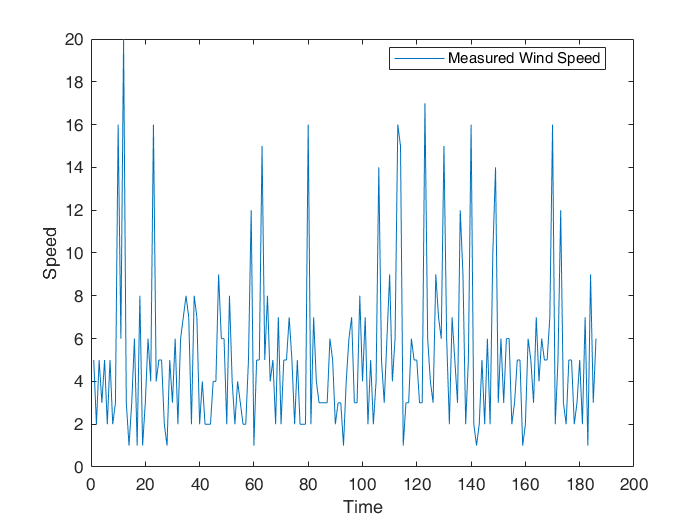

load windData.mat
mins = 1:length(speed); % minute past from the first measurament 

plot(mins,speed);
title('Wind speed measurements')
legend('Measured Wind Speed','location','best');
xlabel('Time');
ylabel('Speed');

### Apply the filter

Moving window methods are ways to process data in smaller batches at a time, typically in order to statistically represent a neighborhood of points in the data. The moving average is a common data smoothing technique that slides a window along the data, computing the mean of the points inside of each window. This can help to eliminate insignificant variations from one data point to the next.

Use the [movmean](https://it.mathworks.com/help/matlab/ref/movmean.html) function to apply a moving average filter. With a suitable windows size we can smooth out the high-speed wind gusts by averaging n samples of the signal.

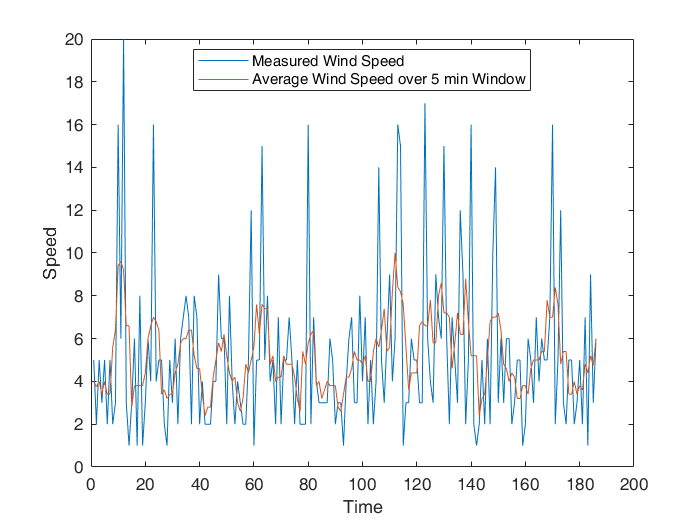

window =5

speed_smoothed = movmean(speed,window); %Apply the Moving Average Filter

plot(mins,speed,mins,speed_smoothed);
title('Wind speed measurements')
legend('Measured Wind Speed',sprintf('Average Wind Speed over %d min Window',window),'location','best');
xlabel('Time');
ylabel('Speed');

## Sharpening: Unsharp masking filter

### Create an example signal

Sharpening filters try to emphasize the details of the signal, finding the differences by the neighborhoods.

A simple yet effective sharpening filter is the unsharp masking filter. To better visualize the effect of this filter, we apply it to a simple ramp signal.

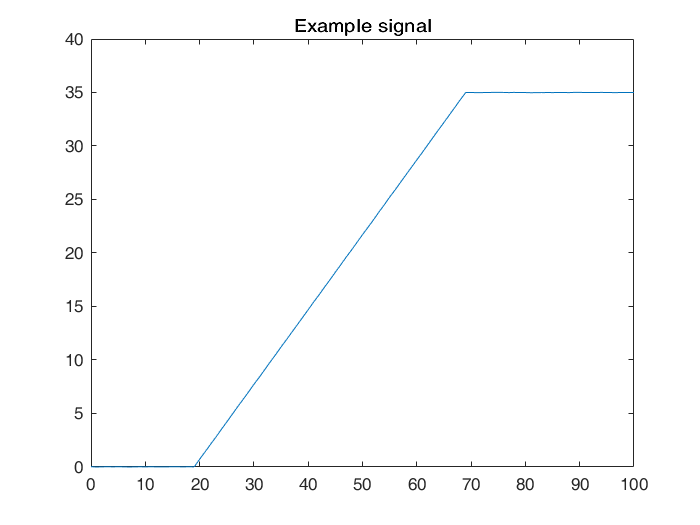

x=0:100;

% Generate a simple ramp signal
y=zeros(size(x));
slope = 0.7; s_start = 20; s_end = 70; 
y(s_start:s_end) = slope .* (0:(s_end-s_start));
y(s_end:end) = slope.*(s_end-s_start);

%Add noise
y=y+ 0.01.*randn(size(x));

plot(x,y);
title('Example signal');

### Apply the filter

Here we perform the unsharp masking method by subtracting a smoothed filtered version of the original image weighted by a constant k.

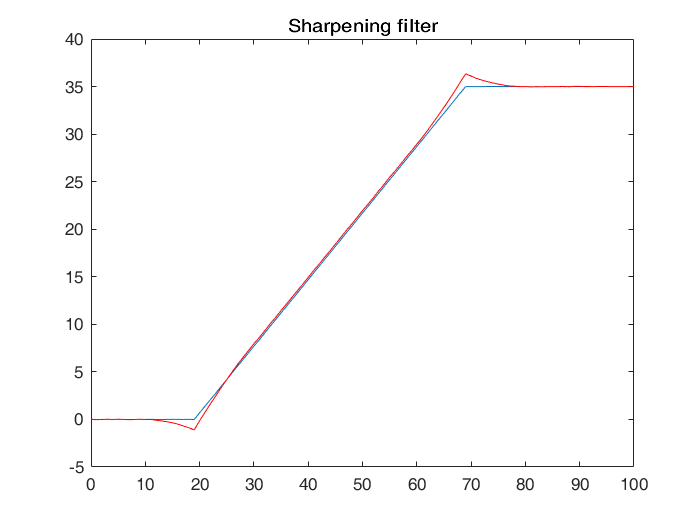

window = 20;
y_smooth = movmean(y,window);
k = 0.7;
y_sharp = y - k.*(y_smooth-y);  % Apply the Unsharp masking filter
plot(x,y,x,y_sharp,'r');
title('Sharpening filter');

## Further Practice

- Try different hyperparameters values for the windows size of the moving average filter. How does the smoothed version change?

- The function [`B = smoothdata(A,method)`](https://it.mathworks.com/help/matlab/ref/smoothdata.html#d122e1205389), permits to perform other smoothing algorithms. Try to change the moving average algorithm with others and understand the effects. 

## Further readings

- [Data smoothing and Outlier Detection](https://it.mathworks.com/help/matlab/data_analysis/data-smoothing-and-outlier-detection.html)